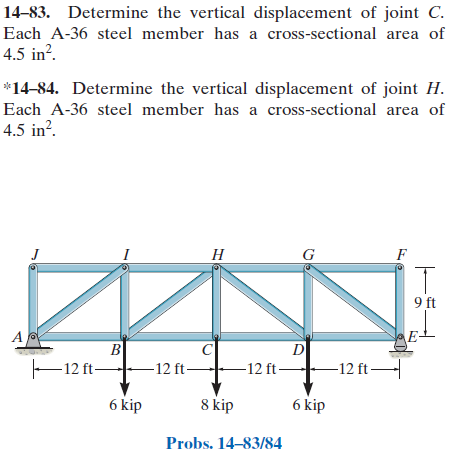

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-83P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-83P-solution-9780136022305) (problem 14-83)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-84P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-84P-solution-9780136022305) (problem 14-84)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = atand(sym(9/12))*u.deg;
jointA = [0 0]*u.ft;
jointB = [12 0]*u.ft;
jointC = [24 0]*u.ft;
jointD = [36 0]*u.ft;
jointE = [48 0]*u.ft;
jointF = [48 9]*u.ft;
jointG = [36 9]*u.ft;
jointH = [24 9]*u.ft;
jointI = [12 9]*u.ft;
jointJ = [0 9]*u.ft;

# member data

E = 29e3*u.ksi;
A = 4.5*u.in^2;

# truss

t = Truss;
t = t.add('reaction', 'Ra', {'Rax' 'Ray'}, jointA);
t = t.add('reaction', 'Re', {0 'Rey'}, jointE);
t = t.add('concentrated', 'Pb', [0 -6]*u.kip, jointB);
t = t.add('concentrated', 'Pc', [0 -8]*u.kip, jointC);
t = t.add('concentrated', 'Pd', [0 -6]*u.kip, jointD);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('joint', 'E', jointE);
t = t.add('joint', 'F', jointF);
t = t.add('joint', 'G', jointG);
t = t.add('joint', 'H', jointH);
t = t.add('joint', 'I', jointI);
t = t.add('joint', 'J', jointJ);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fbc', jointB, jointC, E, A);
t = t.add('member', 'Fcd', jointC, jointD, E, A);
t = t.add('member', 'Fde', jointD, jointE, E, A);
t = t.add('member', 'Ffg', jointF, jointG, E, A);
t = t.add('member', 'Fgh', jointG, jointH, E, A);
t = t.add('member', 'Fhi', jointH, jointI, E, A);
t = t.add('member', 'Fij', jointI, jointJ, E, A);
t = t.add('member', 'Faj', jointA, jointJ, E, A);
t = t.add('member', 'Fbi', jointB, jointI, E, A);
t = t.add('member', 'Fch', jointC, jointH, E, A);
t = t.add('member', 'Fdg', jointD, jointG, E, A);
t = t.add('member', 'Fef', jointE, jointF, E, A);
t = t.add('member', 'Fai', jointA, jointI, E, A);
t = t.add('member', 'Fbh', jointB, jointH, E, A);
t = t.add('member', 'Fdh', jointD, jointH, E, A);
t = t.add('member', 'Feg', jointE, jointG, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua_vpa = vpa(ua, 4) %#ok<NASGU> 

$$ua\_vpa = \left(\begin{array}{cc} \mathrm{uA} & 0\\ \mathrm{vA} & 0\\ \mathrm{uB} & 0.01471\,\mathrm{in}\\ \mathrm{vB} & -0.1133\,\mathrm{in}\\ \mathrm{uC} & 0.03531\,\mathrm{in}\\ \mathrm{vC} & -0.1627\,\mathrm{in}\\ \mathrm{uD} & 0.05591\,\mathrm{in}\\ \mathrm{vD} & -0.1133\,\mathrm{in}\\ \mathrm{uE} & 0.07062\,\mathrm{in}\\ \mathrm{vE} & 0\\ \mathrm{uF} & 0.0206\,\mathrm{in}\\ \mathrm{vF} & 0\\ \mathrm{uG} & 0.0206\,\mathrm{in}\\ \mathrm{vG} & -0.105\,\mathrm{in}\\ \mathrm{uH} & 0.03531\,\mathrm{in}\\ \mathrm{vH} & -0.1561\,\mathrm{in}\\ \mathrm{uI} & 0.05002\,\mathrm{in}\\ \mathrm{vI} & -0.105\,\mathrm{in}\\ \mathrm{uJ} & 0.05002\,\mathrm{in}\\ \mathrm{vJ} & 0 \end{array}\right)$$

# forces on the truss

ma_f_m_vpa = vpa(ma.f.m, 4) %#ok<NASGU> 

$$ma\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & 13.33\,\mathrm{kip}\\ \mathrm{Fbc} & 18.67\,\mathrm{kip}\\ \mathrm{Fcd} & 18.67\,\mathrm{kip}\\ \mathrm{Fde} & 13.33\,\mathrm{kip}\\ \mathrm{Ffg} & 0\\ \mathrm{Fgh} & -13.33\,\mathrm{kip}\\ \mathrm{Fhi} & -13.33\,\mathrm{kip}\\ \mathrm{Fij} & 0\\ \mathrm{Faj} & 0\\ \mathrm{Fbi} & 10.0\,\mathrm{kip}\\ \mathrm{Fch} & 8.0\,\mathrm{kip}\\ \mathrm{Fdg} & 10.0\,\mathrm{kip}\\ \mathrm{Fef} & 0\\ \mathrm{Fai} & -16.67\,\mathrm{kip}\\ \mathrm{Fbh} & -6.667\,\mathrm{kip}\\ \mathrm{Fdh} & -6.667\,\mathrm{kip}\\ \mathrm{Feg} & -16.67\,\mathrm{kip} \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 10\,\mathrm{kip} & 0\\ \text{Re} & 0 & 10\,\mathrm{kip} & 0\\ \mathrm{Pb} & 0 & -6\,\mathrm{kip} & 0\\ \mathrm{Pc} & 0 & -8\,\mathrm{kip} & 0\\ \mathrm{Pd} & 0 & -6\,\mathrm{kip} & 0 \end{array}\right)$$

ma_f_c_vpa = vpa(ma.f.c, 3) %#ok<NASGU> 

$$ma\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Fab} & 13.3\,\mathrm{kip} & 0 & 0\\ \mathrm{Fbc} & 18.7\,\mathrm{kip} & 0 & 0\\ \mathrm{Fcd} & 18.7\,\mathrm{kip} & 0 & 0\\ \mathrm{Fde} & 13.3\,\mathrm{kip} & 0 & 0\\ \mathrm{Ffg} & 0 & 0 & 0\\ \mathrm{Fgh} & 13.3\,\mathrm{kip} & 0 & 0\\ \mathrm{Fhi} & 13.3\,\mathrm{kip} & 0 & 0\\ \mathrm{Fij} & 0 & 0 & 0\\ \mathrm{Faj} & 0 & 0 & 0\\ \mathrm{Fbi} & 0 & 10.0\,\mathrm{kip} & 0\\ \mathrm{Fch} & 0 & 8.0\,\mathrm{kip} & 0\\ \mathrm{Fdg} & 0 & 10.0\,\mathrm{kip} & 0\\ \mathrm{Fef} & 0 & 0 & 0\\ \mathrm{Fai} & -13.3\,\mathrm{kip} & -10.0\,\mathrm{kip} & 0\\ \mathrm{Fbh} & -5.33\,\mathrm{kip} & -4.0\,\mathrm{kip} & 0\\ \mathrm{Fdh} & 5.33\,\mathrm{kip} & -4.0\,\mathrm{kip} & 0\\ \mathrm{Feg} & 13.3\,\mathrm{kip} & -10.0\,\mathrm{kip} & 0 \end{array}\right)$$

la_f_m = la.f.m %#ok<NASGU> 

$$la\_f\_m = \left(\begin{array}{cc} \mathrm{Ra} & 10\,\mathrm{kip}\\ \text{Re} & 10\,\mathrm{kip}\\ \mathrm{Pb} & 6\,\mathrm{kip}\\ \mathrm{Pc} & 8\,\mathrm{kip}\\ \mathrm{Pd} & 6\,\mathrm{kip} \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fbc} & 0\\ \mathrm{Fcd} & 0\\ \mathrm{Fde} & 0\\ \mathrm{Ffg} & 0\\ \mathrm{Fgh} & 120\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fhi} & 120\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fij} & 0\\ \mathrm{Faj} & 0\\ \mathrm{Fbi} & 120\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fch} & 192\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fdg} & 360\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fef} & 0\\ \mathrm{Fai} & 0\\ \mathrm{Fbh} & 48\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fdh} & 144\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Feg} & 480\,\mathrm{ft}\,\mathrm{kip} \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \text{Re} & 0 & 0 & 480\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pb} & 0 & 0 & -72\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pc} & 0 & 0 & -192\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pd} & 0 & 0 & -216\,\mathrm{ft}\,\mathrm{kip} \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & 0\\ \mathrm{Fcd} & 0 & 0 & 0\\ \mathrm{Fde} & 0 & 0 & 0\\ \mathrm{Ffg} & 0 & 0 & 0\\ \mathrm{Fgh} & 0 & 0 & -120\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fhi} & 0 & 0 & -120\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fij} & 0 & 0 & 0\\ \mathrm{Faj} & 0 & 0 & 0\\ \mathrm{Fbi} & 0 & 0 & 120\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fch} & 0 & 0 & 192\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fdg} & 0 & 0 & 360\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fef} & 0 & 0 & 0\\ \mathrm{Fai} & 0 & 0 & 0\\ \mathrm{Fbh} & 0 & 0 & -48\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fdh} & 0 & 0 & -144\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Feg} & 0 & 0 & -480\,\mathrm{ft}\,\mathrm{kip} \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \text{Re} & 480\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pb} & 72\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pc} & 192\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pd} & 216\,\mathrm{ft}\,\mathrm{kip} \end{array}\right)$$

# clean up

assume(old_assum);
clear old_assum;
clear ua_vpa;
clear ma_f_m_vpa la_f_c ma_f_c_vpa la_f_m;
clear ma_m_m la_m_c ma_m_c la_m_m;